close all;
addpath(genpath('~/Documents'));
addpath(genpath('/calculSSD/salome'));

simuDirAll = '/calculSSD/salome/Simulation-28mars';
simuNameW = '/Bone227G-Image1590-F0.06/';
simuNameR = '/Bone227G-Image1590-F1.25/';
filename = '~/Documents/BoneRugosity/RMS/BoneSample/227G/SAMPLE_227G_SLICE_1590.bmp';
segmented = false;
boundaryEndost = ExtractBoundary(filename, segmented); boundaryEndost(2, :) = max(boundaryEndost(2, :)) - boundaryEndost(2, :);
% Compute necessary information, for mor details, check ProfileSpectrum.mlx
delta_x = 9e-3; Fs = 1/delta_x; L = size(boundaryEndost, 2); fc = 2.5/35;
profile = boundaryEndost(2, 2:end) * delta_x; x = (0:L-1)*1/Fs;

frequencies = logspace(log10(1e-3), log10(50), 50); 
meanH = zeros(1, length(frequencies));
for i = 1 : length(frequencies)
    [profile, roughness, xProfile] = GetRoughness(filename, frequencies(i), false);
    meanH(1, i) = mean(roughness);
end
frequencies = frequencies/(10*fc);

% Post-Process
[~, ProbaW, AngleW, ~] = PostProcessing([simuDirAll, simuNameW]);

----------Getting 1D specular transform----------
Elapsed time is 37.698090 seconds.
---------GET SPECULAR TRANSFORM MODELS---------
	Soft Tissues
Elapsed time is 3.343804 seconds.
Elapsed time is 0.543769 seconds.


[~, ProbaR, AngleR, ~] = PostProcessing([simuDirAll, simuNameR]);

----------Getting 1D specular transform----------
Elapsed time is 36.288969 seconds.
---------GET SPECULAR TRANSFORM MODELS---------
	Soft Tissues
Elapsed time is 2.284212 seconds.
Elapsed time is 0.224327 seconds.


# Results of the ex-vivo parametrics study

The objective of this study is to establish quantifiable parameters for assessing the roughness of bone endostium. Existing literature suggests that surface roughness can be effectively quantified by evaluating the **root mean square of height** relative to a planar surface, along with the **correlation length of height**, which provides insights into the horizontal dimension of surface irregularities. However, these parameters have not been characterized within the context of bone.

Consequently, our initial step involves conducting an analysis of bone imagery acquired via X-ray to discern and define these parameters specific to bone morphology.

## Introduction to the notion of waviness

The concepts such as waviness, roughness, and form are central in the study of a surface roughness. By examining the spatial frequency spectrum of a profile, we can discern the distinct  contributions of various components characterized by different frequencies, as illustrated in the following figure.

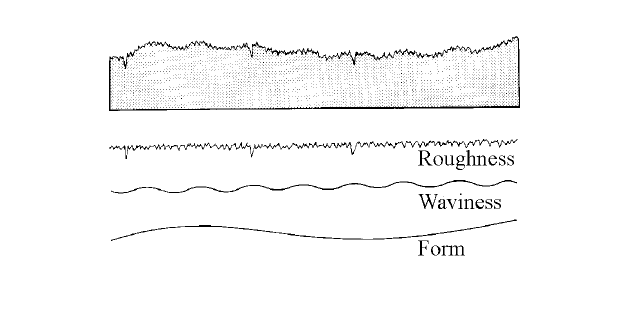

imageData = imread('The-measured-profile-is-the-addition-of-roughness-waviness-and-form.png');
imshow(imageData);

## Analysis of ex-vivo bones

The images where acquired on several ex-vivo bones with various profiles. The endost was extraxted using the `ExtractBoundary.m` function on a binarize image. The resolution of the X-Ray image is $9\mu m$.  

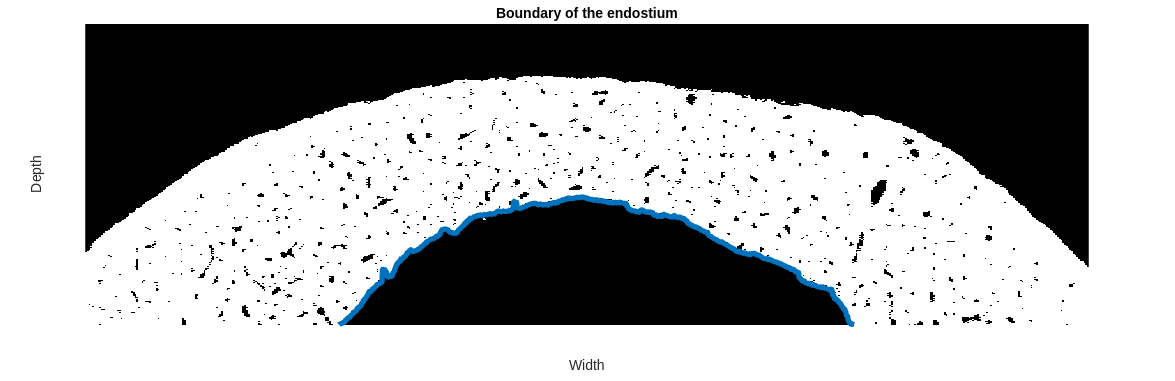

openfig('BoundaryEndost.fig');

### Cut off frequency determination 

In order to extract the rougness and both the waviness and the roughness components of the profile, we need to determine the cutt off frequency of the highpass filter. The usual cut off frequency to obtain *only the roughness* is a frequency that corresponds to a pattern of $0\ldotp 8\textrm{mm}$ thus a frequency $k_{\mathrm{industry}} =1\ldotp 25\;\mathrm{mm⁻¹}$, in the industry. 

In order to obtain the corresponding values for the bone. We computed the mean height of the profile for various cut off frequency. When the mean heigth is equal to zero, we can consider that the parabolic form of the bone as been filtred, we therefore have the *roughness and the waviness* components. 

In order to give significance to our reults, we ploted the mean heigth regarding the frequency that corresponds to the wavelength in the bone, considering a velocity of $c=3500m\ldotp \mathrm{s⁻¹}$ and a temporale frequency $f_{\mathrm{acq}} =2,5\mathrm{Mhz}$: 


$$k_{\lambda } =\frac{1}{\lambda }=\frac{1}{c/f_{\mathrm{acq}} }\approx 0\ldotp 741\;\mathrm{mm⁻¹}$$


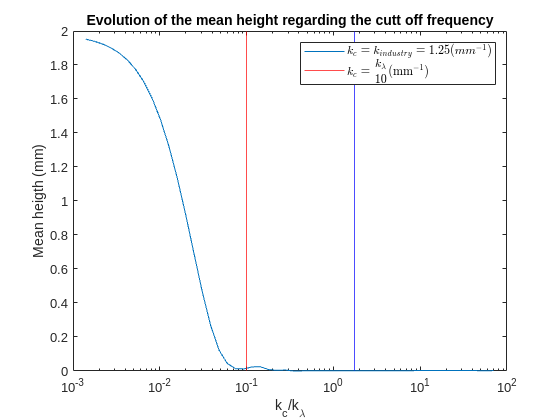

figure
semilogx(frequencies, meanH);
hold on 
xline(1/10, 'r');
xline(1.25/(10*fc), 'b');
hold off
title('Evolution of the mean height regarding the cutt off frequency');
ylabel('Mean heigth (mm)');
xlabel('k{_c}/k{_\lambda}');
legend('$k_c = k_{industry} = 1.25 (mm^{-1})$', '$$k_c = \frac{k_{\lambda}}{10} \mathrm{(mm^{-1})}$$', 'Interpreter', 'latex');

The results allow us to see that the frequency that allow to extract the waviness *and* the roughness, which corresponds to the blue line, is $\frac{k_{\lambda } }{10}\approx 0\ldotp 0741\;\textrm{mm⁻¹}$. The frequency that allow to extract only the roughness, according the the industry is plotted in blue. 

We will know refer to the combination of roughness and waviness as waviness.

### Root mean square of the extracted profile

The profile was filtred using the `highpass` function with the frequencies of interest. 

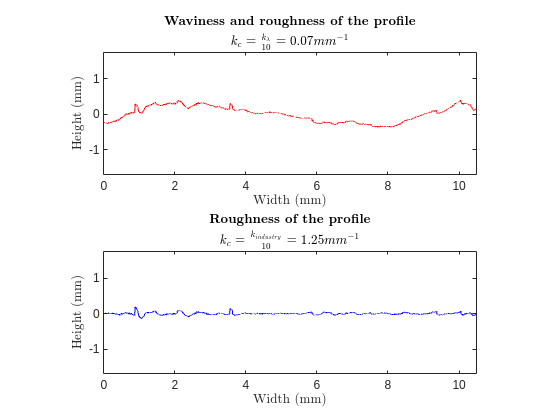

figure
subplot(2,1,1)
plot(x, highpass(profile, 0.07, Fs), 'r');
title('\bf Waviness and roughness of the profile', '$k_c = \frac{k_{\lambda}}{10} = 0.07 mm^{-1}$', 'Interpreter', 'latex');
xlabel('Width (mm)', 'Interpreter', 'latex');
ylabel('Height (mm)', 'Interpreter', 'latex');
axis equal
subplot(2,1,2)
plot(x, highpass(profile, 1.25, Fs), 'b');
title('\bf Roughness of the profile', '$k_c = \frac{k_{industry}}{10} = 1.25 mm^{-1}$', 'Interpreter', 'latex');
xlabel('Width (mm)', 'Interpreter', 'latex');
ylabel('Height (mm)', 'Interpreter', 'latex');
axis equal

We can clearely distinguish from the original profile, the waviness and the roughness. The root mean square of these extracted profiles have distinct root mean square value. The roughness profile as a RMS of ${\textrm{RMS}}_{\textrm{waviness}} \approx 214\mu m$and ${\textrm{RMS}}_{\textrm{roughness}} \approx 33\mu m$. 

### Validation on other bones

These values have been validated on other image of the same bone and on other bones.

## Simulation on waviness and roughness of ex-vivo bones

In order to observe the interaction of the ultrasounds regarding the two type of extracted profile. We did a `SimSonic` simulation with the bone/soft tissu interface being both the roughness and waviness profiles. The original curved profile measured $15\textrm{mm}$. We therefore did a extention of the waviness and roughness to recover the original length of the endosteium and a symmetry in order to reach a geometry of $30\textrm{mm}$ of width. 

The map generated allog side with the specularity map obtained are depicted in the following figure. 

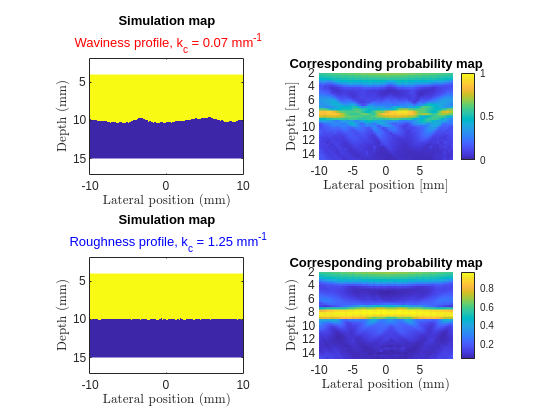

figure
subplot(2,2,1)
[Map,~,~] = SimSonic2DReadMap2D([simuDirAll, simuNameW, 'Geometry.map2D']);
X = 5:0.01:25-0.01; X = X -mean(X);
Z = flipud(4:0.01:15-0.01);
imagesc(X, Z, Map(400:end-1, 500:2499))
axis equal
xlabel('Lateral position  (mm)', Interpreter='latex');
ylabel('Depth (mm)', Interpreter='latex');
title('Simulation map', '\color{red} Waviness profile, k_c = 0.07 mm^{-1}');
subplot(2,2,3)
[Map,~,~] = SimSonic2DReadMap2D([simuDirAll, simuNameR, 'Geometry.map2D']);
X = 5:0.01:25-0.01; X = X -mean(X);
Z = flipud(4:0.01:15-0.01);
imagesc(X, Z, Map(400:end-1, 500:2499))
axis equal
xlabel('Lateral position  (mm)', Interpreter='latex');
ylabel('Depth (mm)', Interpreter='latex');
title('Simulation map', '\color{blue} Roughness profile, k_c = 1.25 mm^{-1}');
subplot(2,2,2)
Xinit = 500;
Zinit = 600;
pcolor(reconstruction.Xmm,reconstruction.Zmm,ProbaW)
xlabel('Lateral position [mm]', Interpreter='latex')
ylabel('Depth [mm]', Interpreter='latex')
colorbar
title('Corresponding probability map')
axis ij image, shading flat
clim([0 1])
subplot(2,2,4)
pcolor(reconstruction.Xmm, reconstruction.Zmm, ProbaR) 
axis tight
title('Corresponding probability map')  
shading flat
xlabel('Lateral position (mm)', Interpreter='latex')
ylabel('Depth (mm)', Interpreter='latex')
axis ij image;
colorbar

The specularity map indicates the probability that the surface at the corresponding pixel is part of a specular interface or rather a diffuse interface. 